# Further Exploration 1: Develop a Model Programmatically

The Regression Learner app provides an easy-to-use interface to evaluate multiple models. For added customization, you can develop your models programmatically in MATLAB.

- Repeat the steps from 1.a. through 4.a. of [Machine Learning for Regression: Part 2](matlab:open('./loadForecastRegression_soln.mlx')) in the **Output inline** mode  . Doing this will allow you to understand and reuse parts of the code for preprocessing and feature extraction.

- Fit a linear regression model to the training data `trainNYC`. See [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html). Use the [`predict`](https://www.mathworks.com/help/stats/linearmodel.predict.html) function to apply the model to test data `testNYC`.

- Similar to step 4.d. in  [Machine Learning for Regression: Part 2](matlab:open('./loadForecastRegression_soln.mlx')), evaluate the model against actual load values for test data and plot the results.

Repeat this process, replacing the linear regression model in step 2 with

- a stepwise regression model (see [`stepwiselm`](https://www.mathworks.com/help/stats/stepwiselm.html)) 

- an ensemble of regression trees (see [`TreeBagger`](https://www.mathworks.com/help/stats/treebagger.html))

In each of the above cases, read the documentation to set the different options and parameters available for the model.

Compare the models.

- Can you tell which model is the best?

- Are there periods where one model performs better than other models?

## **Sample starter solution for **`fitlm`

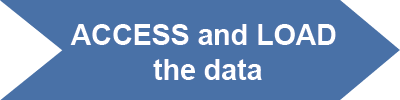

% Load the electricity load data.
load nyiso_cleaned.mat nyiso;

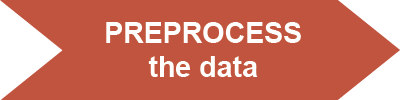

% Extract the data for New York City.
nycData = nyiso(:,"N_Y_C_");

% Change the table column name to be more general.
nycData.Properties.VariableNames = "Load"

% Retime the time series to an hourly granularity.
nycHourly = retime(nycData,"hourly");

% Converr the data to a table for extracting features.
nycHourly = timetable2table(nycHourly);
nycHourly(end,:) = []

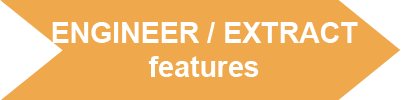

% Extract lag features.
previousLoads = lagmatrix(nycHourly.Load,[1 24 168]);
nycHourly.PreviousLoad = previousLoads(:,1);
nycHourly.PreviousDayLoad = previousLoads(:,2);
nycHourly.PreviousWeekLoad = previousLoads(:,3)

% Extract data and time features.
dates = nycHourly.Date;
nycHourly.DayOfWeek = weekday(dates);
nycHourly.Hour = hour(dates);
nycHourly.Month = month(dates);
nycHourly.Year = year(dates);

% Transform the cyclical time features into sine and cosine components
nycHourly.HourX = sin(2*pi*nycHourly.Hour/24);
nycHourly.HourY = cos(2*pi*nycHourly.Hour/24);

% Convert the months to sin and cos features
nycHourly.MonthX = sin(2*pi*nycHourly.Month/12);
nycHourly.MonthY = cos(2*pi*nycHourly.Month/12);

% Convert the days of week to sin and cos features
nycHourly.DayOfWeekX =sin(2*pi*nycHourly.DayOfWeek/7);
nycHourly.DayOfWeekY = cos(2*pi*nycHourly.DayOfWeek/7);

% Delete the old features
nycHourly.Hour = [];
nycHourly.Month = [];
nycHourly.DayOfWeek = [];

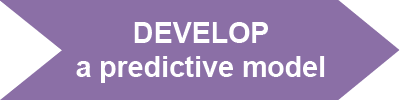

% Split the date into training and test sets.
trainStart = "2017-May-08 00:00";
trainEnd = "2019-Dec-31 23:00";
idxtrain = isbetween(nycHourly.Date, datetime(trainStart,"TimeZone","America/New_York"), ...
                                     datetime(trainEnd,"TimeZone","America/New_York")); 
idxtest = nycHourly.Date > datetime(trainEnd,"TimeZone","America/New_York");
trainNYC = nycHourly(idxtrain,2:end)
testNYC = nycHourly(idxtest,2:end)

% Fit a linear model to predict load.
mdlLM = fitlm(trainNYC,"ResponseVar","Load");

% Apply the model to predict output for test data.
yPredTest = predict(mdlLM,testNYC(:,2:end));

% Evaluate the predictions against actual load values.
plotDataLM = table2timetable(nycHourly(idxtest,:));
plotDataLM.Pred = yPredTest;
plotDataLM.Error = (plotDataLM.Pred - plotDataLM.Load);
rmseLM = sqrt(mean((plotDataLM.Error).^2));

% Plot the predicted versus actual load along with the errors.
plotVars = {["Load" "Pred"], "Error"};
figure
stackedplot(plotDataLM,plotVars, ...
    "Title", ["Comparison of actual and predicted load"; "Test RMSE= " + num2str(rmseLM)]);